# **MEA 313 Project**

**We chose fiat tipo as reference for our calculations**

max. torque = 152 @ 4500 rpm (first point)

max hp = 110 @ 5500 , so the torque will be 142 Nm (second point)

assume T = 132 @ 3900 rpm (third point )

## Car Specifications

clearvars %(delete old variables)

rpmarray = [  4500 , 5500,6000 ]; %RPM ARRAY

torquearray = [ 152 , 142,135 ]; % TORQUE ARRAY

mass = 1695;

weight = 1695 * 9.81 ; 

length = 2.63;

L1= 1.3;

L2= 1.33;

Hieght = 1.49*0.5 ;

CD = 0.31;

mechanical_eff = 0.95;

rho = 1.23; 

fr = 0.015;

AF = 2.22;  

vmax = 192/3.6;

tire_r = 0.315; 

IF = 4.923; 

mew = 0.9;

torque_max = 152;

noshifts = 6 ;

NEMIN = 1000;

NEMAX = 8000;

# **Task 1**

syms Ne ig  vx   % NE and ig are symbolic 


p = polyfit(rpmarray,torquearray,2); %coeff of second degree equation

TE = p(1)*Ne^2 + p(2)*Ne + p(3)  % engine torque formula

$$TE = -2.6667e-06\,{\mathrm{Ne}}^{2}+0.0167\,\mathrm{Ne}+131$$

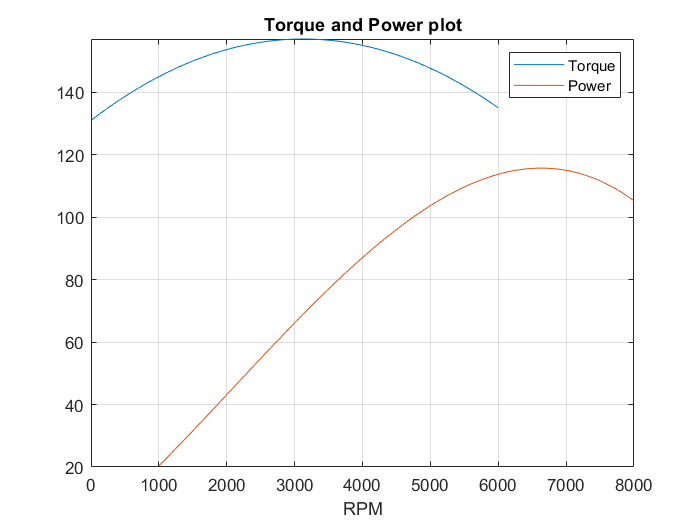


figure(1)

fplot(TE , [0 , 6000]);  % plotting torque curve over a set of rpms

hold on

title('Torque and Power plot') 

xlabel('RPM');

ylabel('');

grid on

power = (2*pi*Ne)/(60) * 0.00134102 * TE ; % power equation
  
fplot(power , [1000, 8000]); % plotting power curve over a set of rpms

legend('Torque','Power')
hold off

# **Task 2**

### ** To get the highst shift one must calculate the total resistance at max speed  vmax=192**


Total_R = weight * fr + 0.5 *rho *CD * AF * vmax^2   % total resistance

Total_R = 1.4533e+03

### TR = FE

  
                        
FE_gbratios = TE  * IF * ig * mechanical_eff / tire_r; % force effecteive 

FE_gbratios =subs(FE_gbratios,ig,2*pi*Ne*tire_r/60/IF/vmax);

solNe = vpasolve( FE_gbratios == Total_R );

solNe = double (solNe); % getting the largest Ne to sub in the ig to get the hiesght shift

ig_highest = 2*pi*solNe(3)*tire_r/60/IF/vmax;

ig_highest = double(ig_highest) %typecasting

ig_highest = 0.9679


% to get the lowest shift and we have the Te max we can simply substitue

ig1 =( L2+Hieght*fr) / (length+mew*Hieght) * ( mew*tire_r ) / (mechanical_eff*torque_max*IF) * weight *cosd(0) ;


      

### to get the other shifts



kg = nthroot(ig1/ig_highest,5) ;  % ratio of the lowest and hieghst shift

gbratios = zeros(noshifts,1);   %array of zeros coloumn vector

gbratios (1) = ig1;

gbratios (noshifts) = ig_highest;


## first method to get the between shifts (geometric)


for n = 2 : noshifts - 1
    
    gbratios(n) = gbratios(n-1)/kg ;
      
    
end


gbratios  %  printing geometric ratios 

gbratios =     2.6946
    2.1956
    1.7891
    1.4578
    1.1878
    0.9679


### plotting ig values vs. Fe values


  
FE_gbratios = sym(zeros(noshifts,1)); % defined as double

figure(2)
  
for i = 1 : noshifts
    
 hold on 
 
title('FE  plot first method ') 

xlabel('VELOCITY in km/hr'); 

ylabel('FE');

grid on


###  Plotting The Fe vs the velocity 


FE_gbratios(i) = subs(TE*gbratios(i)*IF*mechanical_eff/tire_r , Ne , 60*gbratios(i)*IF/pi/2/tire_r*vx/3.6);

fplot(FE_gbratios(i),[NEMIN*2*pi/60/IF/gbratios(i)*tire_r,NEMAX*2*pi/60/IF/gbratios(i)*tire_r*3.6]); % plotting Fe vs velocity

  legend('ig1','ig2','ig3','ig4','ig5','ig6')
end

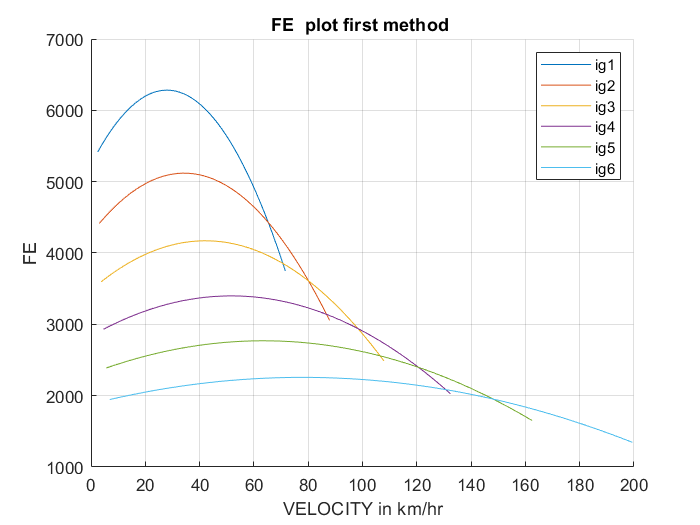


hold off

# **Task 3**

## second method to get between shifts( progressive design )


C_ratios = zeros(noshifts - 2 , 1); % array of zeros coloumn vector

prog_ratios = zeros(noshifts  , 1); % array of zeros coloumn vector

prog_ratios (1) = ig1;

prog_ratios (6) = ig_highest;

cgp = kg ;  % ratio

k = 0.9 ;  % progressive factor 

C_ratios(1) = cgp * k^-1.5;   % getting the first c ratio


for n = 2 : noshifts - 1
    
   C_ratios(n) = k * C_ratios(n-1);
   
   prog_ratios(n)= prog_ratios(n-1)/C_ratios(n-1); % getting the between shifts of the progressive design
   
end

prog_ratios % printing the ratios

prog_ratios =     2.6946
    1.8747
    1.4491
    1.2447
    1.1878
    0.9679


###  Plotting the Fe vs the velocity  for progressive design

 
  
FE_progg = sym(zeros(noshifts,1)); % defined as double

figure(3)
  
for i = 1 : noshifts
    
hold on

title('FE  plot second method') 

xlabel('VELOCITY on km/hr');

ylabel('FE on N');

grid on

FE_progg(i) = subs(TE*prog_ratios(i)*IF*mechanical_eff/tire_r , Ne , 60*prog_ratios(i)*IF/pi/2/tire_r*vx/3.6);


fplot(FE_progg(i),[NEMIN*2*pi/60/IF/prog_ratios(i)*tire_r,NEMAX*2*pi/60/IF/prog_ratios(i)*tire_r*3.6]);
legend('ig1','ig2','ig3','ig4','ig5','ig6')
end

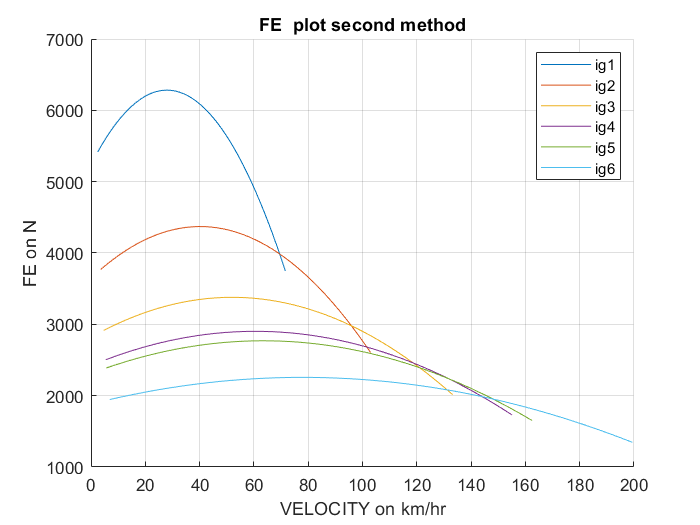



hold off

##  third method ( delta v method )

 

delta_v_ratios =  zeros(noshifts , 1); % crating an array of no of shifts

delta_v_ratios (1) = ig1;

delta_v_ratios (6) = ig_highest;

for n = 2 : noshifts-1
    
    delta_v_ratios(n)= (noshifts-1)/(noshifts-n+(n-1)*cgp^(n-1))*ig1;

end

delta_v_ratios % printing delta Vs ratios

delta_v_ratios =     2.6946
    2.5775
    2.2409
    1.7856
    1.3374
    0.9679


### plotting Fe value for delta v method



FE_deltav = sym(zeros(noshifts,1)); % defined as double

figure(4)
  
for i = 1 : noshifts
    
hold on 

title('FE  plot Third method')

xlabel('VELOCITY');

ylabel('FE');

grid on 

FE_deltav(i) = subs(TE*delta_v_ratios(i)*IF*mechanical_eff/tire_r , Ne , 60*delta_v_ratios(i)*IF/pi/2/tire_r*vx/3.6); 

fplot(FE_deltav(i),[NEMIN*2*pi/60/IF/delta_v_ratios(i)*tire_r,NEMAX*2*pi/60/IF/delta_v_ratios(i)*tire_r*3.6]);

legend('ig1','ig2','ig3','ig4','ig5','ig6')

end

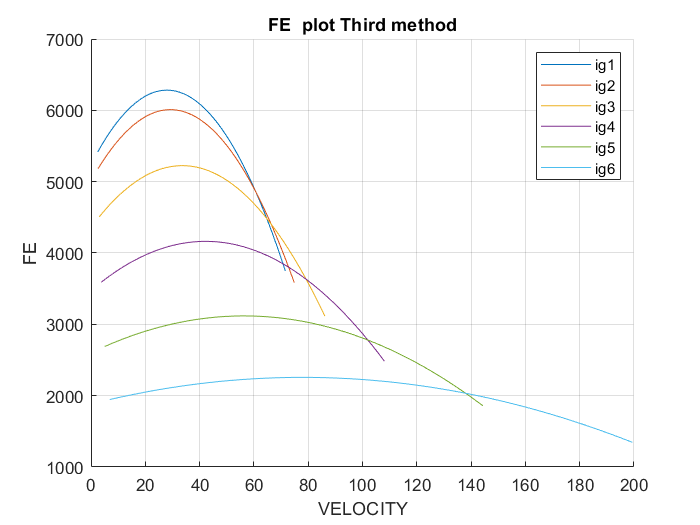



hold off

## upshift and lower speeds

### first the geometric design 

upshift_geometric = vpasolve(FE_gbratios(3)== FE_gbratios(4)); 

third_upshift_geometric_velocity_in_km = double(upshift_geometric(2)); % IN km/hr

lowershift_geometric = vpasolve(FE_gbratios(3)== FE_gbratios(2)); 

third_lowershift_geometric_velocity_in_km = double(lowershift_geometric(2)); % IN km/hr



### second the progressive design 


upshift_progressive =vpasolve( FE_progg(3)== FE_progg(4)); 

third_upshift_progressive_vel_in_km = double(upshift_progressive(2)); % IN km/hr

lowershift_progressive =vpasolve( FE_progg(3)== FE_progg(2)); 

third_lowershift_progressive_vel_in_km = double(lowershift_progressive(2)); % IN km/hr


### third the delta v design


upshift_delta = vpasolve (FE_deltav(3) == FE_deltav(4))  ;

third_upshift_delta_in_km = double(upshift_delta(2)); % IN km/hr

lowershift_delta = vpasolve (FE_deltav(3) == FE_deltav(2)); 

third_lowershift_delta_in_km = double(lowershift_delta(2)); % IN km/hr


### the number of itteration to get the time- distance 

no_of_itterations_geo = ceil((third_upshift_geometric_velocity_in_km-third_lowershift_geometric_velocity_in_km)/2);

no_of_itterations_prog = ceil((third_upshift_progressive_vel_in_km-third_lowershift_progressive_vel_in_km)/2);

no_of_itterations_delta = ceil((third_upshift_delta_in_km-third_lowershift_delta_in_km)/2);


### creating arrays of for the schaduling technique 

### arrays of the geometric design

TR_geo = zeros(no_of_itterations_geo,1);

Ne_geo = zeros(no_of_itterations_geo,1);

Fe_geo = zeros(no_of_itterations_geo,1);

acc_geo = zeros(no_of_itterations_geo,1);

invacc_geo = zeros(no_of_itterations_geo,1);

time_geo = zeros(no_of_itterations_geo,1);

time_acc_geo = zeros(no_of_itterations_geo,1);

distance_geo= zeros(no_of_itterations_geo,1);

distance_acc_geo = zeros(no_of_itterations_geo,1);

### arrays of the progressive  design


TR_prog = zeros(no_of_itterations_prog,1);

Ne_prog = zeros(no_of_itterations_prog,1);

Fe_prog = zeros(no_of_itterations_prog,1);

acc_prog =zeros(no_of_itterations_prog,1);

invacc_prog = zeros(no_of_itterations_prog,1);

time_prog= zeros(no_of_itterations_prog,1);

time_acc_prog = zeros(no_of_itterations_prog,1);

distance_prog = zeros(no_of_itterations_prog,1);

distance_acc_prog =zeros(no_of_itterations_prog,1);



### arrays of the delta v design

TR_delta = zeros(no_of_itterations_delta,1);

Ne_delta = zeros(no_of_itterations_delta,1);

Fe_delta= zeros(no_of_itterations_delta,1);

acc_delta= zeros(no_of_itterations_delta,1);

invacc_delta = zeros(no_of_itterations_delta,1);

time_delta = zeros(no_of_itterations_delta,1);

time_acc_delta = zeros(no_of_itterations_delta,1);

distance_delta = zeros(no_of_itterations_delta,1);

distance_acc_delta = zeros(no_of_itterations_delta,1);




## comparison between different designs

### first the geometric design

#### schadule technique

     i = 1;
for n =third_lowershift_geometric_velocity_in_km : 2 :third_upshift_geometric_velocity_in_km
  
   TR_geo(i) = weight * fr + 0.5 *rho *CD * AF * (n/3.6)^2; % to get the total resistance 
   
   Ne_geo(i) = 60*gbratios(3)*IF/pi/2/tire_r*n/3.6;  % to get rpms
   
   Fe_geo(i) = subs(TE*gbratios(3)*IF*mechanical_eff/tire_r , Ne , Ne_geo(i)); % to get the fe 
   
   acc_geo(i) = (Fe_geo(i)-TR_geo(i))/mass;
   
   invacc_geo(i) = 1/acc_geo(i);
  
   i= i+1;
end

i = 2;
 

#### ** time and distance by using the acc we achieved**

 
for n =third_lowershift_geometric_velocity_in_km : 2 :third_upshift_geometric_velocity_in_km-2

    time_geo(i) =( invacc_geo(i) +  invacc_geo(i-1))*0.5*((2/3.6));  % time for the geometric desing

    time_acc_geo(i)= time_acc_geo(i-1)+time_geo(i); % acc time

    x =0 ;

    distance_geo(i) = ((third_lowershift_geometric_velocity_in_km+x)+(third_lowershift_geometric_velocity_in_km+x+2))/(2*3.6)*time_geo(i);

    distance_acc_geo(i) = distance_acc_geo(i-1)+distance_geo(i); % acc distance

    i = i +1;

    x = x+2;
end


time_acc_geo_schaduale=time_acc_geo(10) % printing the accumolated time

time_acc_geo_schaduale = 3.0570


distance_acc_geo_schaduale=distance_acc_geo(10) % printing the accumolated distance

distance_acc_geo_schaduale = 68.8901

#### **integration technique for geometric design**



FE_geo = subs(TE*gbratios(3)*IF*mechanical_eff/tire_r , Ne , 60*gbratios(3)*IF/pi/2/tire_r*vx); % Fe as a symbolic equation

TR_geo = weight * fr + 0.5 *rho *CD * AF * (vx)^2; % total resistance as a symbolic function

f = mass/(FE_geo-TR_geo); % the integrated function

time_geo_int = int(f,third_lowershift_geometric_velocity_in_km/3.6 ,(third_upshift_geometric_velocity_in_km)/3.6); % integration for function "f" betweend the lower and upper velocity

time_geo_int = double(time_geo_int);

disatnce_geo_int = int(f*vx,third_lowershift_geometric_velocity_in_km/3.6 ,(third_upshift_geometric_velocity_in_km-2)/3.6); % integration for function "f" betweend the lower and upper velocity

disatnce_geo_int= double(disatnce_geo_int)  % printing the distance in the integration technique

disatnce_geo_int = 66.6472


time_geo_int= double(time_geo_int) % printing the time via the integration technique

time_geo_int = 3.0977

### second the progressive design 

#### time and distance by schadule technique

i = 1;
for n =third_lowershift_progressive_vel_in_km : 2 :third_upshift_progressive_vel_in_km

  
   TR_prog(i) = weight * fr + 0.5 *rho *CD * AF * (n/3.6)^2; 
   
   Ne_prog(i) = 60*prog_ratios(3)*IF/pi/2/tire_r*n/3.6;
   
   Fe_prog(i) = subs(TE*prog_ratios(3)*IF*mechanical_eff/tire_r , Ne , Ne_prog(i));
   
   acc_prog(i) = (Fe_prog(i)-TR_prog(i))/mass;
   
   invacc_prog(i) = 1/acc_prog(i);
  
   i= i+1;
end

i = 2;


#### time and distance by schadule technique

for n =third_lowershift_progressive_vel_in_km : 2 :third_upshift_progressive_vel_in_km-2

    time_prog(i) =( invacc_prog(i) +  invacc_prog(i-1))*0.5*((2/3.6));

    time_acc_prog(i)= time_acc_prog(i-1)+time_prog(i);

    x =0 ;

    distance_prog(i) = ((third_lowershift_progressive_vel_in_km+x)+(third_lowershift_progressive_vel_in_km+x+2))/(2*3.6)*time_prog(i);


    distance_acc_prog(i) = distance_acc_prog(i-1)+distance_prog(i);

    i = i +1;

    x = x+2;

end

distance_acc_prog_schaduale=distance_acc_prog(12) % printing the distance accumolated 

distance_acc_prog_schaduale = 132.4982


time_acc_prog_schaduale=time_acc_prog(12) % printing the time accumolated 

time_acc_prog_schaduale = 4.9216

### integration to get the time and distance for progressive design

FE_prog = subs(TE*prog_ratios(3)*IF*mechanical_eff/tire_r , Ne , 60*prog_ratios(3)*IF/pi/2/tire_r*vx);

TR_prog = weight * fr + 0.5 *rho *CD * AF * (vx)^2;

f = mass/(FE_prog-TR_prog);

time_prog_int = int(f,third_lowershift_progressive_vel_in_km/3.6 ,(third_upshift_progressive_vel_in_km)/3.6); % integration for function "f" betweend the lower and upper velocity

time_prog_int = double(time_prog_int);

disatnce_prog_int = int (f*vx,third_lowershift_progressive_vel_in_km/3.6 ,(third_upshift_progressive_vel_in_km-2)/3.6); % integration for function "f" betweend the lower and upper velocity

disatnce_prog_int= double ( disatnce_prog_int) % printing the distance via the integration

disatnce_prog_int = 136.1511


time_prog_int= double ( time_prog_int) % printing the time via integration

time_prog_int = 5.1175

### third delta design

#### schadule technique


i = 1;
for n =third_lowershift_delta_in_km : 2 :third_upshift_delta_in_km
  
   TR_delta(i) = weight * fr + 0.5 *rho *CD * AF * (n/3.6)^2;
   
   Ne_delta(i) = 60*delta_v_ratios(3)*IF/pi/2/tire_r*n/3.6;
   
   Fe_delta(i) = subs(TE*delta_v_ratios(3)*IF*mechanical_eff/tire_r , Ne , Ne_delta(i));
   
   acc_delta(i) = (Fe_delta(i)-TR_delta(i))/mass;
   
   invacc_delta(i) = 1/acc_delta(i);
  
   i= i+1;
end
i = 2;
for n =third_lowershift_delta_in_km : 2 :third_upshift_delta_in_km-2
    
time_delta(i) =( invacc_delta(i) +  invacc_delta(i-1))*0.5*((2/3.6));

time_acc_delta(i)= time_acc_delta(i-1)+time_delta(i);

x =0 ;

distance_delta(i) = ((third_lowershift_delta_in_km+x)+(third_lowershift_delta_in_km+x+2))/(2*3.6)*time_delta(i);

distance_acc_delta(i) = distance_acc_delta(i-1)+distance_delta(i);
i = i +1;
x = x+2;
end

distance_acc_delta_schaduale=distance_acc_delta(7) % printing the distance

distance_acc_delta_schaduale = 29.0994


time_acc_delta_schaduale=time_acc_delta(7) % printing the time

time_acc_delta_schaduale = 1.5554

#### integration technique

FE_delta= subs(TE*delta_v_ratios(3)*IF*mechanical_eff/tire_r , Ne , 60*delta_v_ratios(3)*IF/pi/2/tire_r*vx);

TR_delta= weight * fr + 0.5 *rho *CD * AF * (vx)^2;

f = mass/(FE_delta-TR_delta);

time_delta_int = int(f,third_lowershift_delta_in_km/3.6 ,(third_upshift_delta_in_km)/3.6); % integration for function "f" betweend the lower and upper velocity

disatnce_delta_int = int (f*vx,third_lowershift_delta_in_km/3.6 ,(third_upshift_delta_in_km-2)/3.6);% integration for function "f" betweend the lower and upper velocity

disatnce_delta_int= double(disatnce_delta_int) % printing distance by the integration tech

disatnce_delta_int = 27.9228


time_delta_int= double(time_delta_int) % printing the time by the integration tech

time_delta_int = 1.6864




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%